Aerial robot Lab report

Prepared by Melkamu Amare 

M2SAAS-2024

Submitted to: Mr. Islam Mahmoud

Universite Evry Paris-Saclay

# Exercise(1)

Consider an airplane patterned after the twin-engine Beechcraft Queen Air executive transport flying at an 

altitude of 10Km. The airplane weight is 38, 220N, wing area is 27.3m2, aspect ratio is 7.5, 

Oswald efficiency factor is 0.9, and parasite drag coefficient Cdo = 0.03 calculate the following:

S = 27.3;
W = 38220;
rho = 0.4135;
h = 10000;

e = 0.9;
AR = 7.5;
CD0 = 0.03;
K = 1/(pi*e*AR);

syms V
TRZL = 0.5*rho*V^2*S*CD0; % zero left drag/ thrust
TRLD = 2*K*S*(W/S)^2/(rho*V^2); % zero left drag/ thrust
TR11 = TRZL + TRLD; % total thrust or drag


1. the thrust required to fly at a velocity of 350km/h = 97.22 m/s. 

% V = 350km/h = 97.22m/s

V1 = 97.22

V1 = 97.2200

TR1 = eval(subs(TR11, V1))

TR1 = 2.8917e+03

2. The minimum thrust required and its corresponding velocity graphically and analytically.

The thrust required for horizontal flight must compensate the different formas of drag, i.e.

- The *parassitic drag*, varying with q ∼ V2.

- The *induced drag*, varying with 1/q ∼ 1/V2.

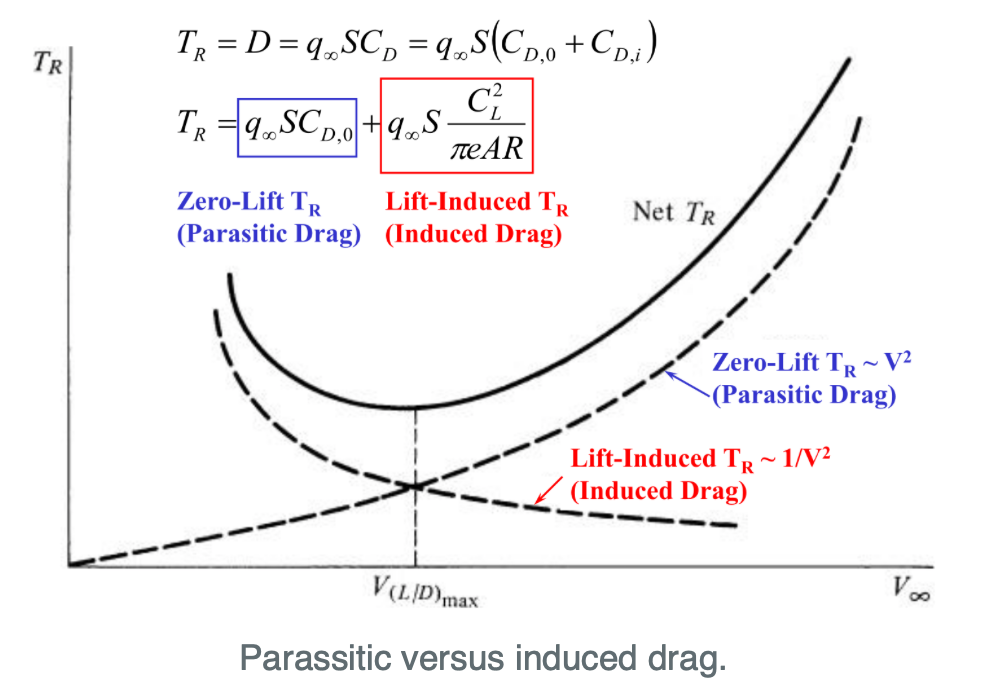

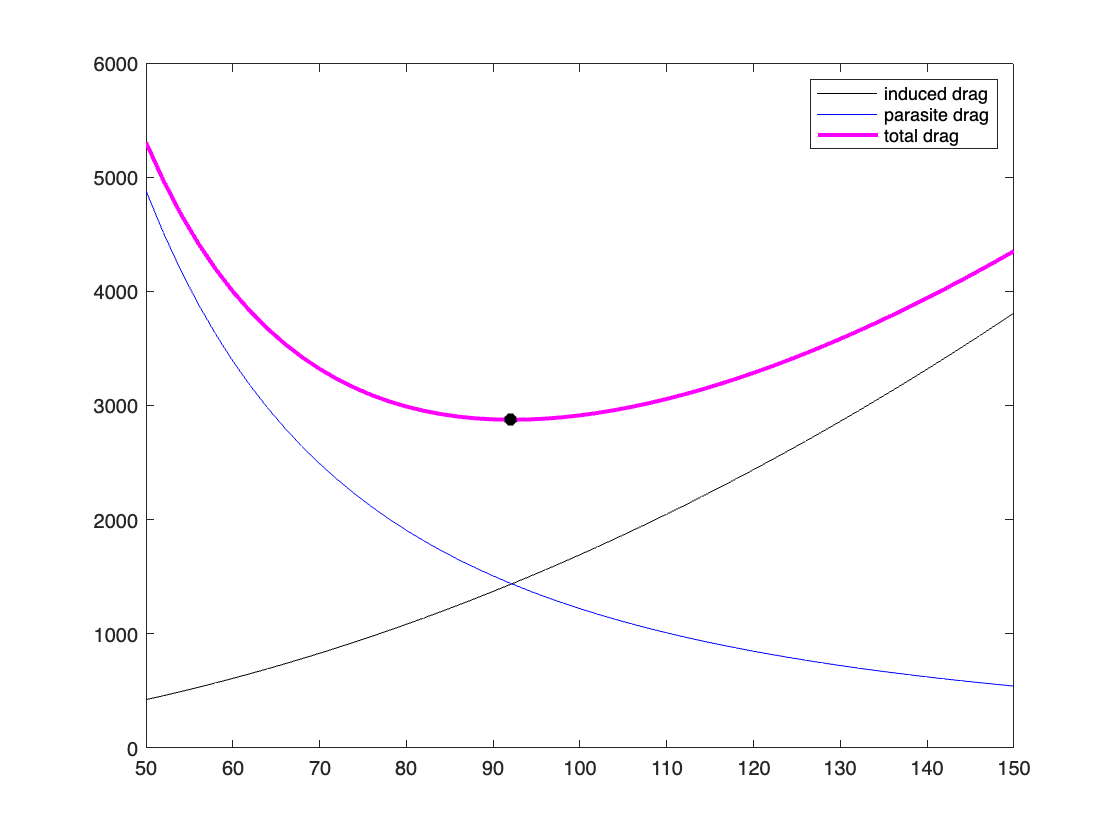

VV = 50:2:150;
TRZL1 = eval(subs(TRZL, VV)); % induced drag
TRLD1 = eval(subs(TRLD, VV)); % parasite drag
TRX = TRLD1 + TRZL1; % total drag or net thrust
figure
plot(VV, TRZL1, 'k-')
hold on
plot(VV, TRLD1, 'b-')
plot(VV, TRX, 'm-', LineWidth=2);

TRmin = islocalmin(TRX);
plot(VV(TRmin), TRX(TRmin), 'k*', LineWidth=3);
hold off
legend('induced drag', 'parasite drag', 'total drag');

It can be also proved analytically that, assuming a parabolic drag polar, the condition for flight at minimum TR occurs 

when the the aircraft develops a drag coefficient whose value is given by the two equal halves: CD0=CDi.

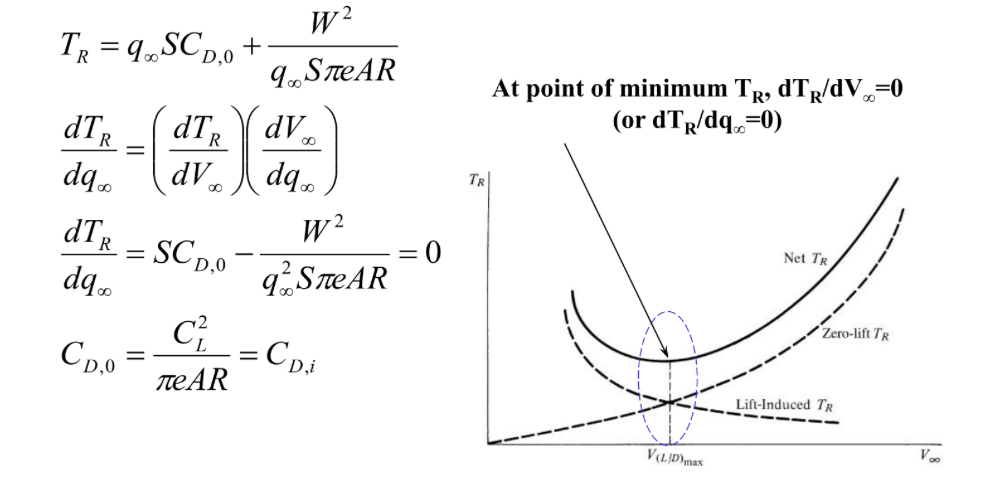

CD,o = CD,¡ at minimum TR and maximum L/D, i.e **CD = 2CD0**

Zero-Lift Drag = Induced Drag at minimum TR and maximum L/D

Vmin1 = (sqrt(2*W*sqrt(K/CD0)/(rho*S)))

Vmin1 = 92.1399

TR = 0.5*rho*Vmin1.^2*S*2*CD0

TR = 2.8751e+03

 3. The minimum thrust required and its corresponding velocity if the aircraft is to fly at an altitude of 7Km

The altitude of the aircraft has inversely related with the density of the air

                           **  rho ~ 1/h**

                  @h = 7km , rho = 0.615

                  @h = 10km, rho = 0.4135

h2 = 7000;
rho2 = 0.615;

syms V;
Vmin22 = (sqrt(2*W*sqrt(K/CD0)/(rho2*S))) % min velocity at 7km

Vmin22 = 75.5523

TR2 = (0.5*rho2*Vmin22^2*S*2*CD0) % total min thrust at 7km

TR2 = 2.8751e+03

4. the minimum velocity of the aircraft knowing that CLmax = 1.2 and its corresponding required thrust.

Here is just a substitution of values in the following formula

                                    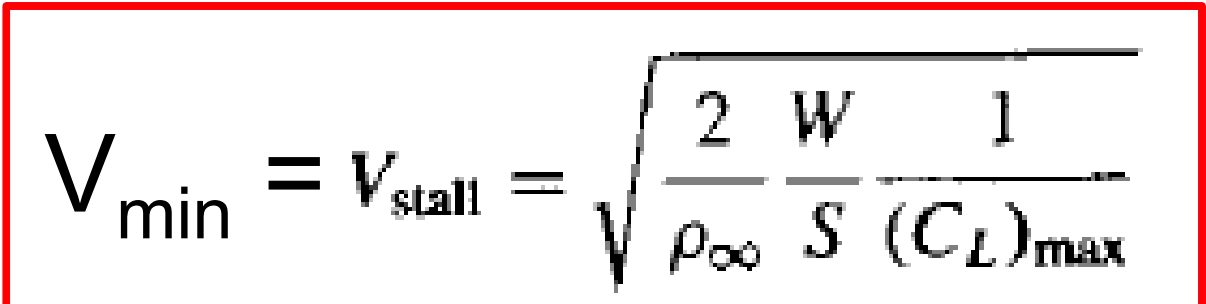

CLmax = 1.2;
Vmin2 = sqrt(2*W/(rho*S*CLmax)) % min velocity

Vmin2 = 75.1191

TR11 = 0.5*rho*Vmin2^2*S*CD0 + 2*K*S*(W/S)^2/(rho*Vmin2^2) % total thrust at min velocity

TR11 = 3.1183e+03

5. the maximum range if the aircraft is gliding from 10Km altitude

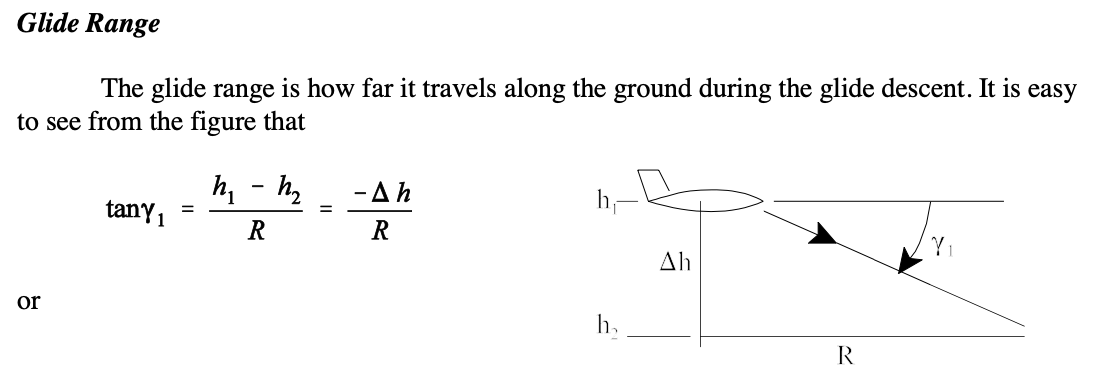

               

Small Glide Angle Assumption

In most cases, the glide angle will be small for an equilibrium glide. Under these

circumstances, we can make the following approximations :

                              

                                       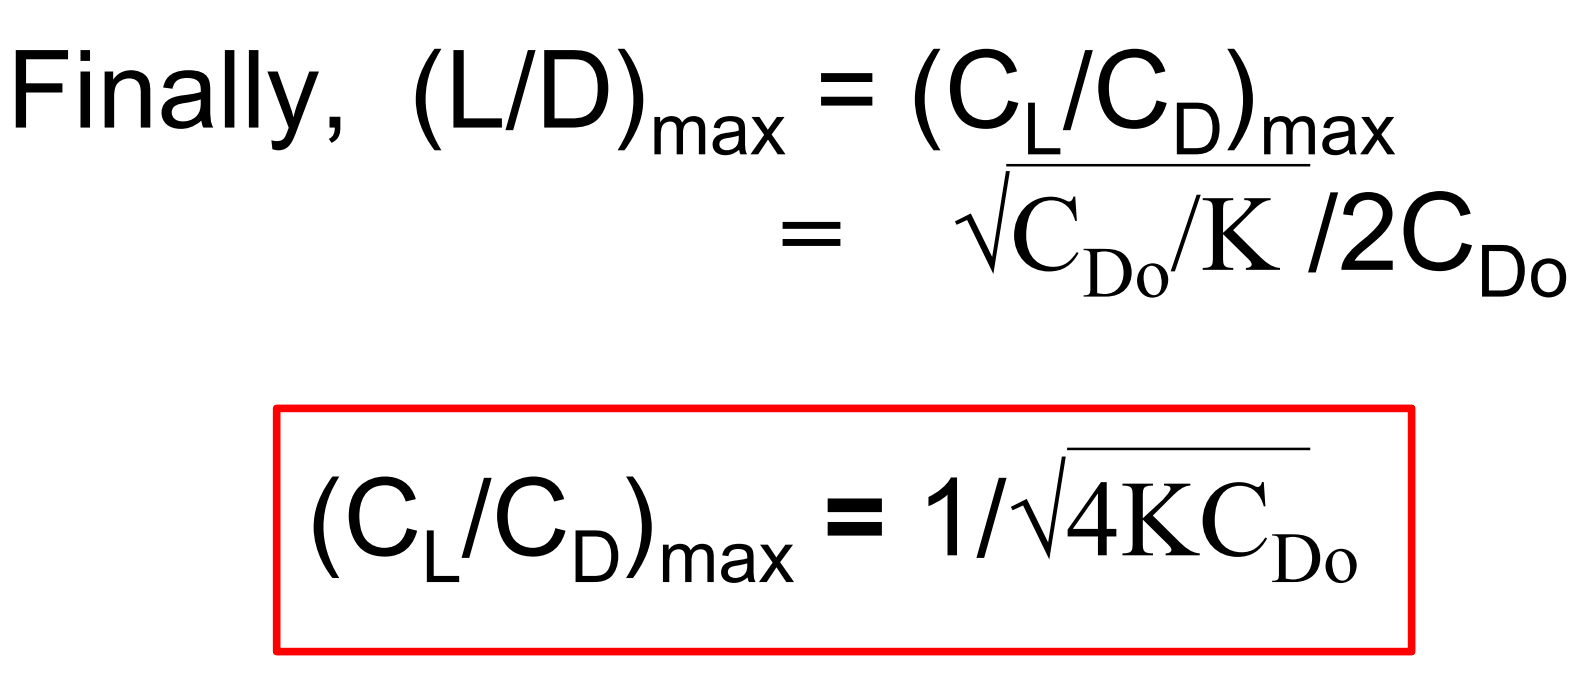

The most important result of this assumption is that we can make the approximation that 

                              = sqrt(4*K*CDo)                                     

tanTmin = sqrt(4*CD0*K); % in rad
tanTmin_inDeg = tanTmin*180/pi  % in degree

tanTmin_inDeg = 4.3101

R = h/tanTmin; % range in meter
RinKM = R/1000 % range in Kilo meter

RinKM = 132.9340